%load data
imgFolder = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB*/*.pgm');
images = [];
for j = 1:length(imgFolder)
    cropn = imgFolder(j).name;
    cropf = imgFolder(j).folder;
    data = imread(strcat(cropf,"/",cropn));
    [n,m]=size(data);
    im = reshape(data,[],1);
    images = [images,im];
end

a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB01/*.pgm');
numfaces(1) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB02/*.pgm');
numfaces(2) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB03/*.pgm');
numfaces(3) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB04/*.pgm');
numfaces(4) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB05/*.pgm');
numfaces(5) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB06/*.pgm');
numfaces(6) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB07/*.pgm');
numfaces(7) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB08/*.pgm');
numfaces(8) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB09/*.pgm');
numfaces(9) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB10/*.pgm');
numfaces(10) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB11/*.pgm');
numfaces(11) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB12/*.pgm');
numfaces(12) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB13/*.pgm');
numfaces(13) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB15/*.pgm');
numfaces(14) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB16/*.pgm');
numfaces(15) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB17/*.pgm');
numfaces(16) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB18/*.pgm');
numfaces(17) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB19/*.pgm');
numfaces(18) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB20/*.pgm');
numfaces(19) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB21/*.pgm');
numfaces(20) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB22/*.pgm');
numfaces(21) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB23/*.pgm');
numfaces(22) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB24/*.pgm');
numfaces(23) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB25/*.pgm');
numfaces(24) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB26/*.pgm');
numfaces(25) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB27/*.pgm');
numfaces(26) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB28/*.pgm');
numfaces(27) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB29/*.pgm');
numfaces(28) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB30/*.pgm');
numfaces(29) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB31/*.pgm');
numfaces(30) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB32/*.pgm');
numfaces(31) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB33/*.pgm');
numfaces(32) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB34/*.pgm');
numfaces(33) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB35/*.pgm');
numfaces(34) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB36/*.pgm');
numfaces(35) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB37/*.pgm');
numfaces(36) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB38/*.pgm');
numfaces(37) = size(a,1);
a = dir('/MATLAB Drive/yalefaces_cropped/CroppedYale/yaleB39/*.pgm');
numfaces(38) = size(a,1);

%load uncropped data
imgFolder = dir('/MATLAB Drive/yalefaces/yalefaces/subject*');
images_unc = [];
for j = 1:length(imgFolder)
    cropn = imgFolder(j).name;
    cropf = imgFolder(j).folder;
    data = imread(strcat(cropf,"/",cropn));
    [p,q] = size(data);
    im_unc = reshape(data,[],1);
    images_unc = [images_unc,im_unc];
end
images_unc  = double(images_unc);


images = double(images);

close all
[U,S,V] = svd(images,'econ');

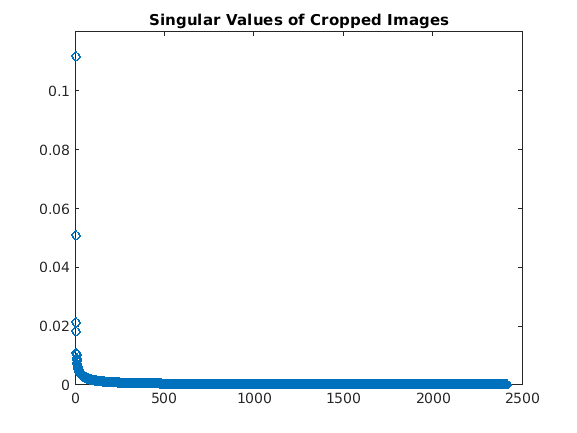

close all;
figure(1)
plot(diag(S)/sum(diag(S)),'o','LineWidth',2)
title('Singular Values of Cropped Images')

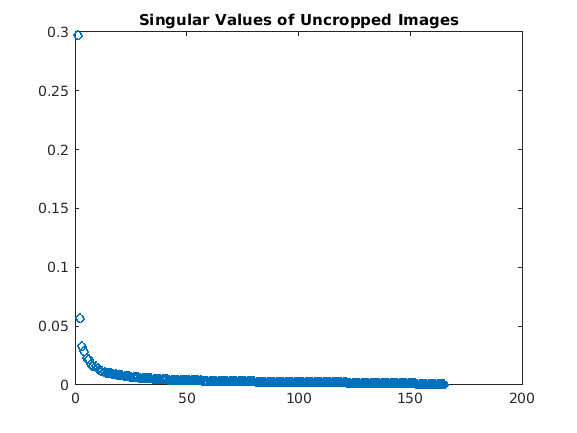

%svd on uncropped data
[u,s,v] = svd(images_unc,'econ');
figure(2)
plot(diag(s)/sum(diag(s)),'o','Linewidth',2);
title('Singular Values of Uncropped Images')

r_unc = size(find(diag(s)/sum(diag(s)) > .001),1);
r = size(find(diag(S)/sum(diag(S)) > .001),1);

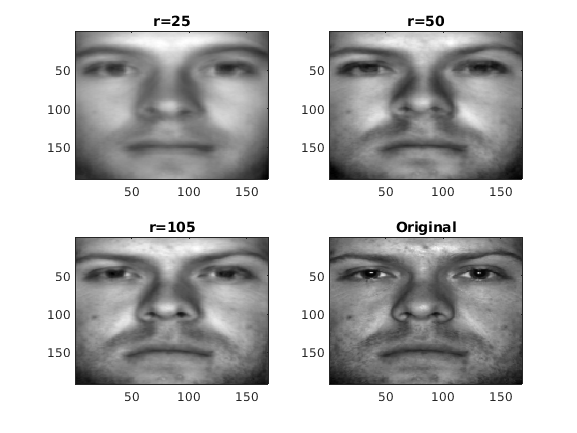

%recreate low rank  approximation of cropped image
rcheck = [25;50;105];
for jj = 1:length(rcheck)
    image_lr = U(:,1:rcheck(jj))*S(1:rcheck(jj),1:rcheck(jj))*V(:,1:rcheck(jj))';
    figure(3)
    subplot(2,2,jj)
    imagesc(reshape(image_lr(:,1),[n,m])), colormap gray
    title(['r=',num2str(rcheck(jj))]);
end
subplot(2,2,4)
imagesc(reshape(images(:,1),[n,m])), colormap gray
title('Original')

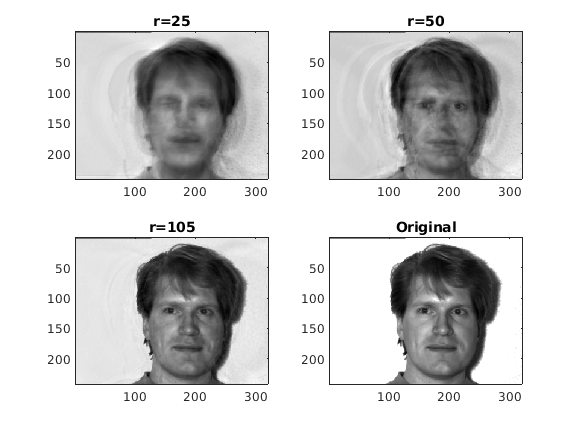

%low rank approx of un cropped images
rcheck2 = [25;50;r_unc];
for jj = 1:length(rcheck)
    image_unc_lr = u(:,1:rcheck2(jj))*s(1:rcheck2(jj),1:rcheck2(jj))*v(:,1:rcheck2(jj))';
    figure(4)
    subplot(2,2,jj)
    imagesc(reshape(image_unc_lr(:,1),[p,q])), colormap gray
    title(['r=',num2str(rcheck2(jj))]);
end
subplot(2,2,4)
imagesc(reshape(images_unc(:,1),[p,q])), colormap gray
title('Original')

ac = [];
for j = 1:6
    x = randperm(sum(numfaces));
    train = images(:,x(1:sum(numfaces(1:30))));
    test = images(:,x(sum(numfaces(1:30))+1:end));
    %create labels
    mm = sum(numfaces);
    labels = zeros(mm,1);
    count = 1;
    for i = 1:38
        labels(count:count+numfaces(i)-1) = i; 
        count = count+numfaces(i);
    end

%k-means classifaction of people
    k = 38;
    [indx,C] = kmeans(train',k);
    [~,idx_test] = pdist2(C,test','euclidean','Smallest',1);
    test_labels = labels(x(sum(numfaces(1:30))+1:end));
%calculate accuarcy
   corLabel =  test_labels - idx_test';
   numCor = find(~corLabel);
   ac = [ac;length(numCor)/size(test_labels,1)];

   end


Error using save
Unable to write file matlab.mat: No space left on device.

%mean accuracy of k mean
kmeans_ac = mean(ac)

kmeans_ac = 0.0241

% %naivebayes
% ac = [];
     %x = randperm(sum(numfaces));
%     train = images(:,x(1:sum(numfaces(1:30))));
%     test = images(:,x(sum(numfaces(1:30)+1):end));
%     %create labels
%     mm = sum(numfaces);
%     labels = zeros(mm,1);
%     count = 1;
%     for i = 1:38
%         labels(count:count+numfaces(i)-1) = i; 
%         count = count+numfaces(i);
%     end
    train_labels = labels(x(1:sum(numfaces(1:30))));
%     test_labels = labels(x(sum(numfaces(1:30)+1):end));
% %naive bayes
%    nb = fitcnb(train',train_labels, 'CrossVal','on');
%    % test 
%     
% ac_nb = loss(nb,test',test_labels)

%KNN
kNNmdl = fitcknn(images',labels);
CVKNNMdl = crossval(kNNmdl);
classError = kfoldLoss(CVKNNMdl);


%Gender sort
%extract females
ifem = [5,14,21,26,27,31,33,36];
idx_fem = [];
for ii = 1:length(ifem)
    idx_fem = [idx_fem, sum(numfaces(1:ifem(ii)-1))+1:sum(numfaces(1:ifem(ii)-1))+numfaces(ifem(ii))]; 
end
images_fem = images(:,idx_fem);
labels_fem = labels(idx_fem);


%extract males
idx_male = 1:sum(numfaces(1:4));
for jj = 1:length(ifem)-1
    idx_male = [idx_male, sum(numfaces(1:ifem(jj)))+1:sum(numfaces(1:ifem(jj+1)-1))];
    
end
idx_male = [idx_male,sum(numfaces(1:36))+1:2414];
images_male = images(:,idx_male);
labels_male = labels(idx_male);

%gender labels
labels_gen = zeros(2414,1);
labels_gen(idx_fem,1) = 1;
labels_gen(idx_male,1) = 2;

SVMmdl = fitcsvm(images', labels_gen,'CrossVal','on');

SVMloss = kfoldLoss(SVMmdl)

SVMloss = 0.1251

%CART
tree = fitctree(images',labels_gen,'CrossVal','on');
treeError = kfoldLoss(tree);

%test 3
GMModel = fitgmdist(images,2);

idx = cluster(GMModel,images);

%K-means test 3
idx = kmeans(images',3);

% for j = 1:3
%     x = randperm(sum(numfaces));
%     train = images(:,x(1:sum(numfaces(1:30))));
%     test = images(:,x(sum(numfaces(1:30))+1:end));
% 
% 
%     
%    end

%look at faces in each group
group1 = find(idx==1);
group2 = find(idx==2);
group3 = find(idx==3);

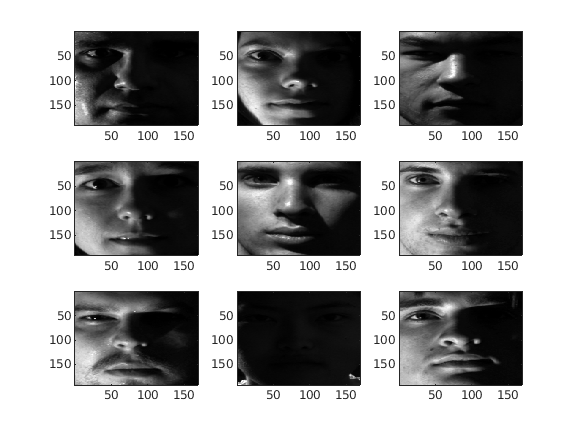

num1 = randperm(801,9);
num2 = randperm(727,9);
num3 = randperm(866,9);

for jj = 1:9
    figure(5)
    subplot(3,3,jj)
    imagesc(reshape(images(:,group1(num1(jj))),[n,m])), colormap gray
    
end

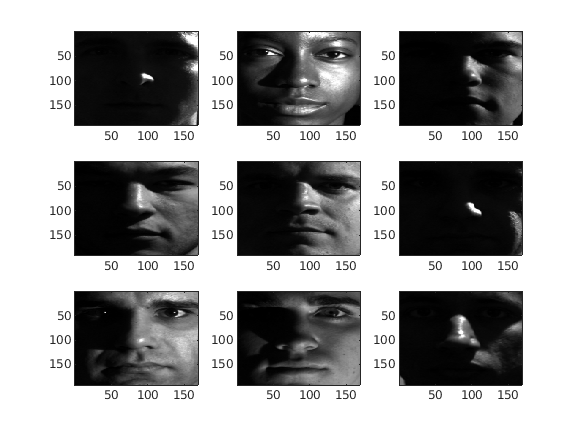


for jj = 1:9
    figure(6)
    subplot(3,3,jj)
    imagesc(reshape(images(:,group2(num2(jj))),[n,m])), colormap gray
    
end

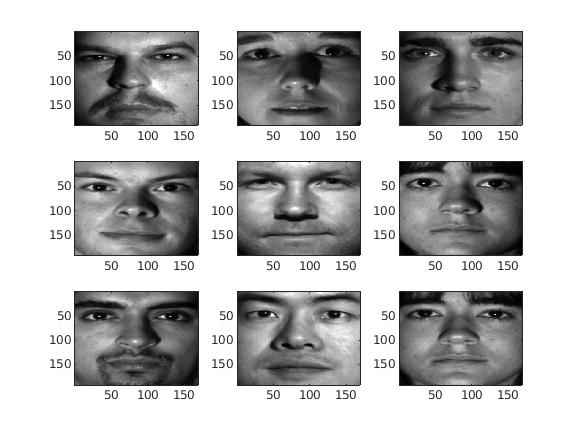


for jj = 1:9
    figure(7)
    subplot(3,3,jj)
    imagesc(reshape(images(:,group3(num3(jj))),[n,m])), colormap gray
    
end

%extract 1 image for each person
for i = 1:38
    oneImage(:,i) = images(:,sum(numfaces(1:i))-20);
end

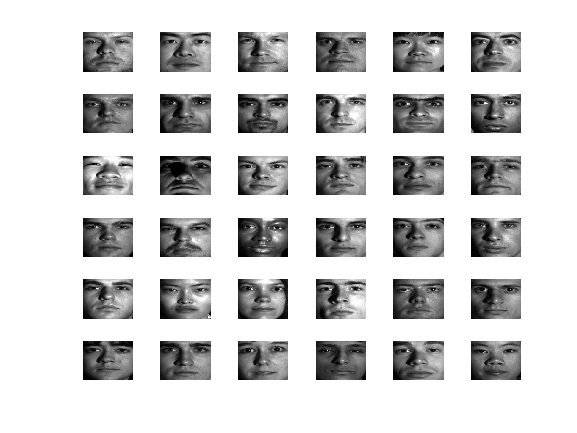

for jj = 1:36
    figure(9)
    subplot(6,6,jj)
    imagesc(reshape(oneImage(:,jj),[n,m])), colormap gray
    set(gca,'visible','off')
  
    
end

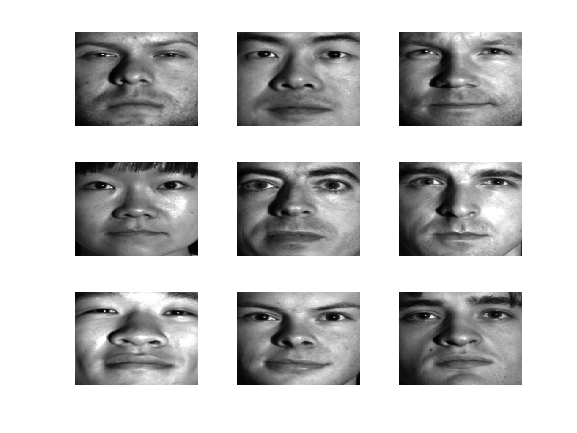

pplsort = kmeans(oneImage',2);
gr1 = find(pplsort==1);
gr2 = find(pplsort==2);

for jj = 1:9
    figure(16)
    subplot(3,3,jj)
    imagesc(reshape(oneImage(:,gr1(jj)),[n,m])), colormap gray
    set(gca,'visible','off')
end

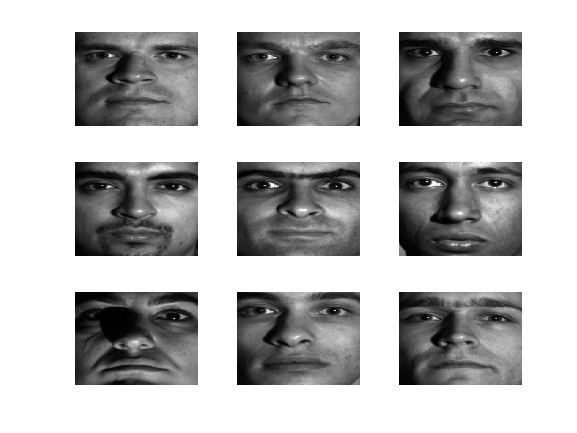


for jj = 1:9
    figure(17)
    subplot(3,3,jj)
    imagesc(reshape(oneImage(:,gr2(jj)),[n,m])), colormap gray
    set(gca,'visible','off')
end

oneImagesort = kmeans(oneImage,2);

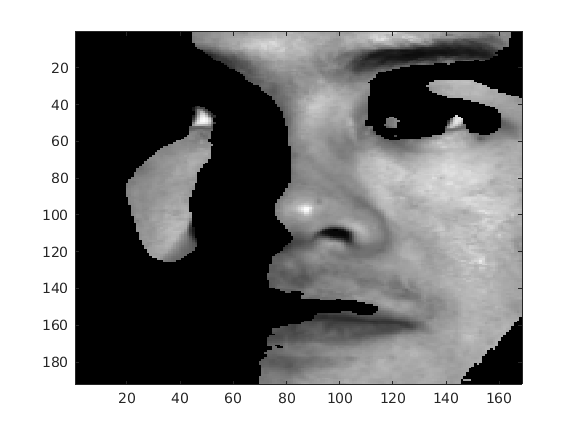

group1 = find(oneImagesort==1);
group2 = find(oneImagesort==2);

clear puzface1
puzface1 = oneImage(:,2);
puzface1(group2) = 0;


figure(15)
%subplot(2,1,1)
imagesc(reshape(puzface1,[n,m])), colormap gray

%subplot(2,1,2)
%imagesc(reshape(oneImage(:,2),[n,m])), colormap gray